tic
clc
clear
Scenarios=["Scenario 1.xlsx";"Scenario 2.xlsx";"Scenario 3.xlsx";"Scenario 4.xlsx";"Properties.xlsx"];
properties_1=readmatrix("Properties.xlsx","Sheet","Properties of A_I");
properties_2=readmatrix("Properties.xlsx","Sheet","Properties of A_II");
properties_3=readmatrix("Properties.xlsx","Sheet","Properties of A_IV");
properties_4=readmatrix("Properties.xlsx","Sheet","Properties of A_V");
properties_5=readmatrix("Properties.xlsx","Sheet","Properties of A_VI");
properties_6=readmatrix("Properties.xlsx","Sheet","Properties of A_VIII");
properties_7=readmatrix("Properties.xlsx","Sheet","Properties of B_II");
properties_8=readmatrix("Properties.xlsx","Sheet","Master Control");
properties_9=readmatrix("Properties.xlsx","Sheet","AC Properties");

if properties_8(17,2) ~= 5
properties_1=readmatrix(Scenarios(properties_8(17,2)),"Sheet","Properties of A_I");
properties_2=readmatrix(Scenarios(properties_8(17,2)),"Sheet","Properties of A_II");
properties_3=readmatrix(Scenarios(properties_8(17,2)),"Sheet","Properties of A_IV");
properties_4=readmatrix(Scenarios(properties_8(17,2)),"Sheet","Properties of A_V");
properties_5=readmatrix(Scenarios(properties_8(17,2)),"Sheet","Properties of A_VI");
properties_6=readmatrix(Scenarios(properties_8(17,2)),"Sheet","Properties of A_VIII");
properties_7=readmatrix(Scenarios(properties_8(17,2)),"Sheet","Properties of B_II");
properties_9=readmatrix(Scenarios(properties_8(17,2)),"Sheet","AC Properties");
end

run A_I.mlx
run A_IV.mlx
run A_VIII.mlx
run A_V.mlx
run A_II.mlx
run A_VI.mlx
run B_II.mlx
run Refigration_unit.mlx
model=["Model_Refrigeration_ON.slx";"Model_Refrigeration_OFF.slx";"Model_Refrigeration_Constant.slx"];
sim(model(properties_8(16,2)))

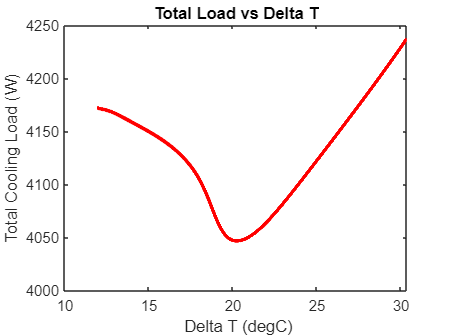

%Graphs
load("total_load.mat");
load("T_room_data.mat");
T_room_plot=T_room_data(2,:);
delta_T=T_env-T_room_plot;
total_load_plot=total_load(2,:);
total_load_plot=total_load_plot';
delta_T=delta_T';
T_room_plot=T_room_plot';
run Results.mlx
plot(delta_T,total_load_plot,'-r','LineWidth',2.5)
title("Total Load vs Delta T");
xlabel(" Delta T (degC)");
ylabel("Total Cooling Load (W)");

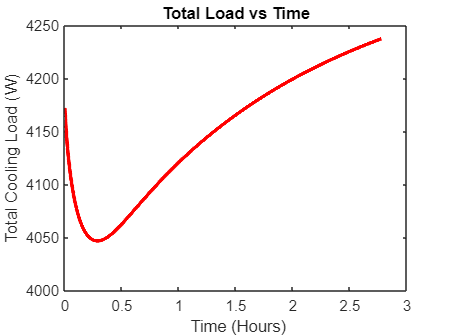

plot(tout/3600,total_load_plot,'-r','LineWidth',2.5)
title("Total Load vs Time");
xlabel(" Time (Hours)");
ylabel("Total Cooling Load (W)");
axis("auto");

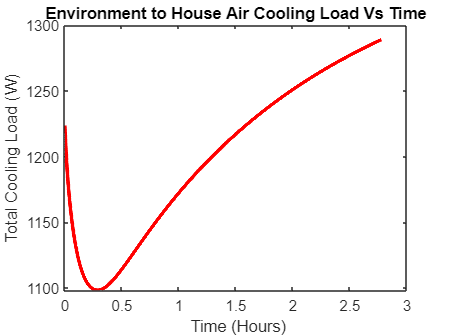

plot(tout/3600,Heat_Environment,'-r','LineWidth',2.5)
title("Environment to House Air Cooling Load Vs Time");
xlabel(" Time (Hours)");
ylabel("Total Cooling Load (W)");
axis("auto");

%Compilation
toc

Elapsed time is 270.895208 seconds.
